% =========================================================================
% 轨迹生成脚本：多点连续直线规划 (Multi-Point Cartesian Path)
% 目标：依次经过多个空间路点 (P1 -> P2 -> P3 ...)
% =========================================================================
clear; clc; close all;

%% 1. 定义路点 (Waypoints) 和 时间
% 每一行是一个点的 [x, y, z] 坐标
waypoints = [
    0.15,  0.0,  0.1;  % P1 (起点)
    0.25,  0.2,  0.2;  % P2
    0.30, -0.2,  0.3;  % P3
    0.20,  0.5,  0.4   % P4 (终点)
];

% 定义每一段的运动时间 (秒)
% 也就是: P1->P2用2秒, P2->P3用1.5秒, P3->P4用2秒
segment_times = [1, 1, 1]; 

% 检查维度是否匹配
[num_points, ~] = size(waypoints);
num_segments = num_points - 1;

if length(segment_times) ~= num_segments
    % 如果没指定具体时间，默认每一段 2 秒
    warning('时间参数与路段数不匹配，自动设为每段 2.0 秒');
    segment_times = ones(1, num_segments) * 2.0;
end

%% 2. 预先检查所有路点的 IK 可行性
fprintf('正在检查所有路点的工作空间可行性...\n');

正在检查所有路点的工作空间可行性...


try
    for i = 1:num_points
        q_check = inverse_kinematics(waypoints(i,1), waypoints(i,2), waypoints(i,3));
    end
    fprintf('>> 所有路点检查通过。\n');
catch ME
    error('错误：第 %d 个路点 (%.2f, %.2f, %.2f) 超出工作空间！', ...
        i, waypoints(i,1), waypoints(i,2), waypoints(i,3));
end

>> 所有路点检查通过。



%% 3. 分段生成并拼接轨迹
dt = 0.0001; % 控制周期 0.1ms

% 初始化总数据容器
total_t = [];
total_q = [];
total_pos = []; % 用于画图验证

current_start_time = 0;

fprintf('开始生成多段轨迹...\n');

开始生成多段轨迹...



for k = 1:num_segments
    % --- 获取当前段的起止点 ---
    P_start = waypoints(k, :);
    P_end   = waypoints(k+1, :);
    T_seg   = segment_times(k);
    
    % --- 生成当前段的时间向量 ---
    % 注意：去掉第一个点，防止与上一段的最后一个点时间重叠(除第一段外)
    if k == 1
        t_seg_vec = 0 : dt : T_seg;
    else
        t_seg_vec = dt : dt : T_seg; % 从 dt 开始，避免 t=0 重复
    end
    
    num_steps = length(t_seg_vec);
    
    % --- 笛卡尔空间插值 (五次多项式) ---
    q_seg = zeros(3, num_steps);
    pos_seg = zeros(3, num_steps);
    
    for i = 1:num_steps
        tau = t_seg_vec(i) / T_seg;
        if tau > 1, tau = 1; end
        
        % 五次多项式 s(t): 0 -> 1
        % 特性: 起止速度、加速度均为 0 (Stop-and-Go 模式)
        s = 10*tau^3 - 15*tau^4 + 6*tau^5;
        
        % 线性插值坐标: P(t) = P_start + s * (P_end - P_start)
        P_curr = P_start + (P_end - P_start) * s;
        pos_seg(:, i) = P_curr';
        
        % 逆解
        try
            q_seg(:, i) = inverse_kinematics(P_curr(1), P_curr(2), P_curr(3));
        catch
            error('在第 %d 段轨迹中间发生逆解错误！', k);
        end
    end
    
    % --- 数据拼接到总容器 ---
    % 时间需要加上当前的起始偏移量
    total_t = [total_t, current_start_time + t_seg_vec];
    total_q = [total_q, q_seg];
    total_pos = [total_pos, pos_seg];
    
    % 更新下一段的起始时间
    current_start_time = current_start_time + T_seg;
end

%% 4. 全局数值微分 (速度 & 加速度)
% 在拼接完所有位置后，统一求导，保证边界处数据连续
num_total_steps = length(total_t);
total_dq  = zeros(3, num_total_steps);
total_ddq = zeros(3, num_total_steps);

for j = 1:3
    % 使用 gradient 进行数值微分
    total_dq(j, :)  = gradient(total_q(j, :), dt);
    total_ddq(j, :) = gradient(total_dq(j, :), dt);
end

%% 5. 转换为 Simulink 格式
% 必须转置为 [N x 3]
ts_q   = timeseries(total_q.', total_t);
ts_dq  = timeseries(total_dq.', total_t);
ts_ddq = timeseries(total_ddq.', total_t);

fprintf('多点轨迹生成完毕！总时长: %.2f 秒\n', total_t(end));

多点轨迹生成完毕！总时长: 3.00 秒


fprintf('请在 Simulink 使用变量: ts_q, ts_dq, ts_ddq\n');

请在 Simulink 使用变量: ts_q, ts_dq, ts_ddq


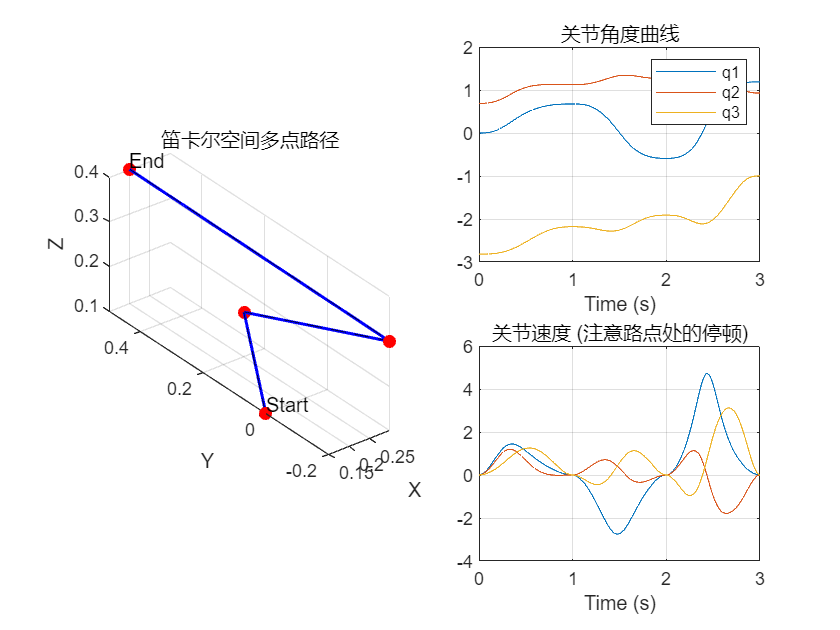


%% 6. 同步初始状态
x0_robot = [total_q(:,1); 0; 0; 0]; 
assignin('base', 'x0_robot', x0_robot);

%% 7. 绘图验证
figure('Color', 'w', 'Name', '多点轨迹验证');

% 图1: 3D 空间路径
subplot(2,2,[1 3]);
plot3(total_pos(1,:), total_pos(2,:), total_pos(3,:), 'b-', 'LineWidth', 1.5); hold on;
% 标记所有路点
plot3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
% 连线示意
plot3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 'k--', 'LineWidth', 0.5);

text(waypoints(1,1), waypoints(1,2), waypoints(1,3)+0.02, 'Start');
text(waypoints(end,1), waypoints(end,2), waypoints(end,3)+0.02, 'End');

grid on; axis equal; view(3);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('笛卡尔空间多点路径');


% 图2: 关节角度
subplot(2,2,2);
plot(total_t, total_q); grid on;
title('关节角度曲线'); legend('q1','q2','q3');
xlabel('Time (s)');

% 图3: 关节速度 
subplot(2,2,4);
plot(total_t, total_dq); grid on;
title('关节速度 (注意路点处的停顿)');
xlabel('Time (s)');



% =========================================================================
% 局部函数: 逆运动学 (同前)
% =========================================================================

function q = inverse_kinematics(x, y, z)
    d1 = 0.1; a2 = 0.4; a3 = 0.3;

    q1 = atan2(y, x);
    
    r = sqrt(x^2 + y^2);
    z_eff = z - d1;
    D_sq = r^2 + z_eff^2;
    
    cos_q3 = (D_sq - a2^2 - a3^2) / (2 * a2 * a3);
    cos_q3 = max(min(cos_q3, 1), -1);
    q3 = -acos(cos_q3); 

    alpha = atan2(z_eff, r);
    k1 = a2 + a3 * cos(q3);
    k2 = a3 * sin(q3);
    q2 = alpha - atan2(k2, k1);

    q = [q1; q2; q3];
end